clear;
close all
clc

rho_in = 1000;       % Density of water [kg/m^3] at 273.15 K {Incropera & DeWitt}
mu = 1750e-6;       % Viscosity of water [N*s/m^2] at 273.15 K {Incropera & DeWitt}
d_h = 20/1000;       % Hydraulic diameter of pipe [m]
p_in = 101320;       % Inlet pressure [Pa]
u_in = 0.175;         % Inlet velocity [m/s]
alpha = 0.6;        % Underrelaxation constant (between 0 and 1)
nu = mu/rho_in;      % Kinematic viscosity
N_cells = 5;            % Number of computational cells
L = 10;             % Length of pipe [m]

% Set up the distance array
dx = L/(N_cells-1);           % [m]
x = (0:N_cells-1) * dx;

% Initialize arrays (aligns with Equation 10 and Equation 11 from the paper)
u = ones(1, N_cells) * u_in;        % Velocity array [m/s], initialized to inlet velocity
p = ones(1, N_cells) * p_in;        % Pressure array [Pa], initialized to inlet pressure
rho = ones(1, N_cells) * rho_in;    % Density array [kg/m^3], initialized to inlet density
u_star = u;                      % Predicted velocity array, initialized to initial velocity
p_star = p;                      % Predicted pressure array, initialized to initial pressure
p_prime = zeros(1, N_cells);            % Pressure correction array, initialized to zero
u_prime = zeros(1, N_cells);            % Velocity correction array, initialized to zero

Smass = zeros(1, N_cells);         % Mass source term array, initialized to zero
Smom = arrayfun(@(r, u) fric(r, u, d_h, mu, L), rho, u) % Momentum source term array (Equation 68)

Smom =   -0.012250000000000  -0.012250000000000  -0.012250000000000  -0.012250000000000  -0.012250000000000



Sprs_star = zeros(1, N_cells);         % Pressure source star array, initialized to zero

% Calculate the time-step (based on Courant and diffusive conditions, Equation 45)
dt = dx/u_in;
dt = min(dt, (dx*dx)/4/nu);

% Iterate until convergence
error = inf;             % Error, initialized at inf
tolerance = 1e-6;        % Tolerance
iteration = 0;            % Current iteration number
iterationMax = 1;        % Maximum iteration number

while (error > tolerance) && (iteration < iterationMax)

    %%% 0. New time step each iteration
    dt = min(dx/u_in, (dx^2)/(4*nu));

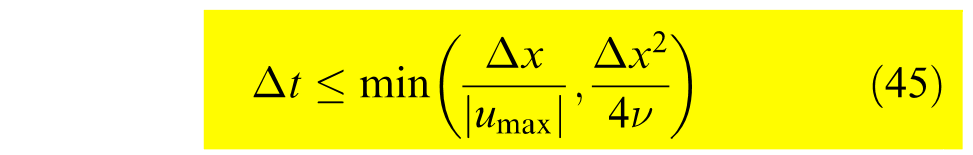

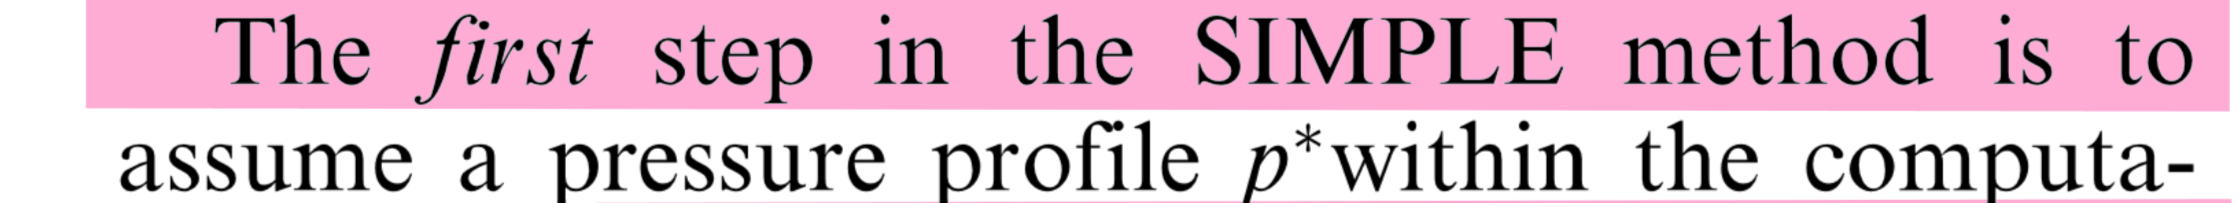

    %%% 1. Guess the pressure 
    p_star(2:end-1) = p(2:end-1)

    % Specify the BCs
    p_star(1) = p_in;
    
    Smom(N_cells) = fric(rho(N_cells), u_star(N_cells), d_h, mu, L);
    Smass(N_cells) = calculate_mass_source(rho(N_cells), u_star(N_cells), dx);
    Sprs_star(N_cells) = Smom(N_cells) - 2*u_star(N_cells)*Smass(N_cells) + 4*mu/3*(u_star(N_cells) - 2*u_star(N_cells) + u_star(N_cells-1))/ (dx^2);

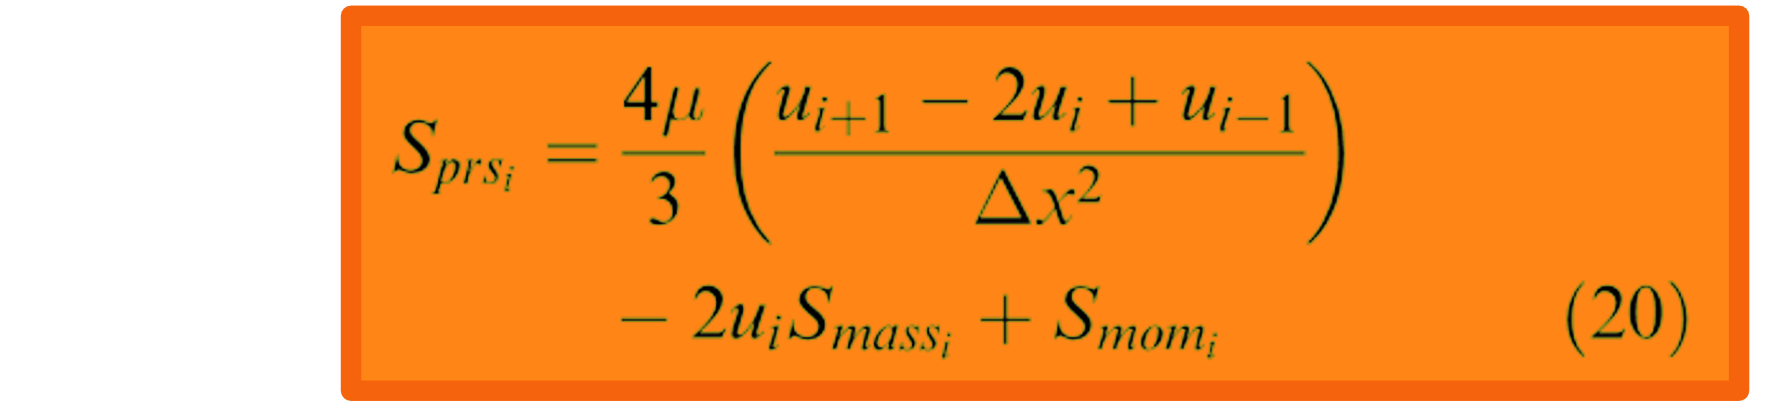                 where u_(i+1) = u(i) and S_mass = 0

    p_star(N_cells) = p_star(N_cells-1) + Sprs_star(N_cells)*dx; % extrapolation

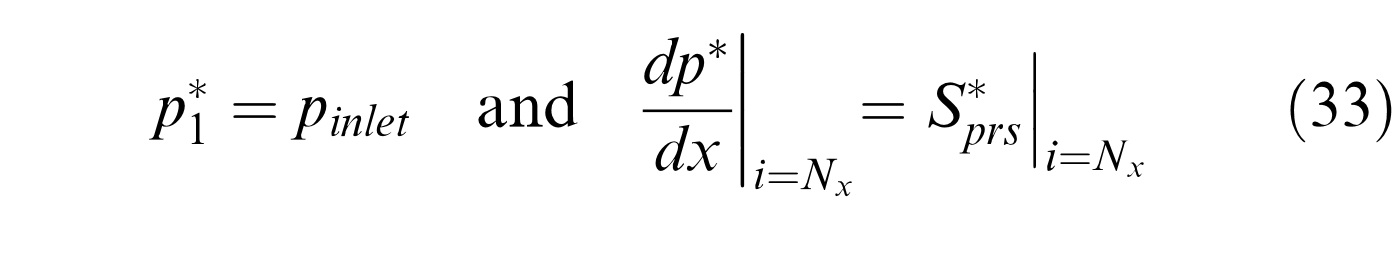

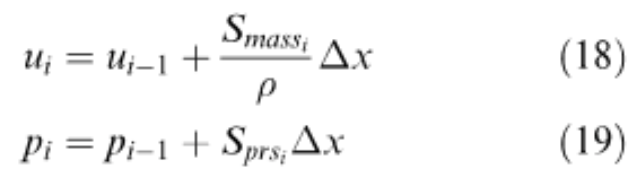$u_i =u_{\left(i-1\right)} +\frac{S_{\textrm{mass}} }{\rho \;}*\Delta \;x\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(18\right)$

    %%% 2. Solve the momentum equations to find the velocity components (Equation 25) %%%
    % FINDING u_star for internal nodes and boundaries!!!

    % internal nodes first
    for i=2:N_cells-1

        sub_error = inf;
        sub_iteration = 0;
        sub_iterationMax = 10000;

        while ((sub_error > tolerance) && (sub_iteration < sub_iterationMax))
            uold = u_star(i);
            % Calculate the momentum source term (Equation 68)
            Smom(i) = fric(rho(i), u_star(i), d_h, mu, L);
            % Calculate the initial velocity guess
            u_star(i) = u(i) + dt*(4*nu/3/dx/dx*(u(i+1)-2*u(i)+u(i-1)) + Smom(i)/rho(i) - (u(i+1)*u(i+1)-u(i)*u(i))/dx - (p_star(i)-p_star(i-1))/rho(i)/dx);
            sub_error = max(sub_error, abs(u_star(i)-uold));
            sub_iteration = sub_iteration + 1;
        end
    end

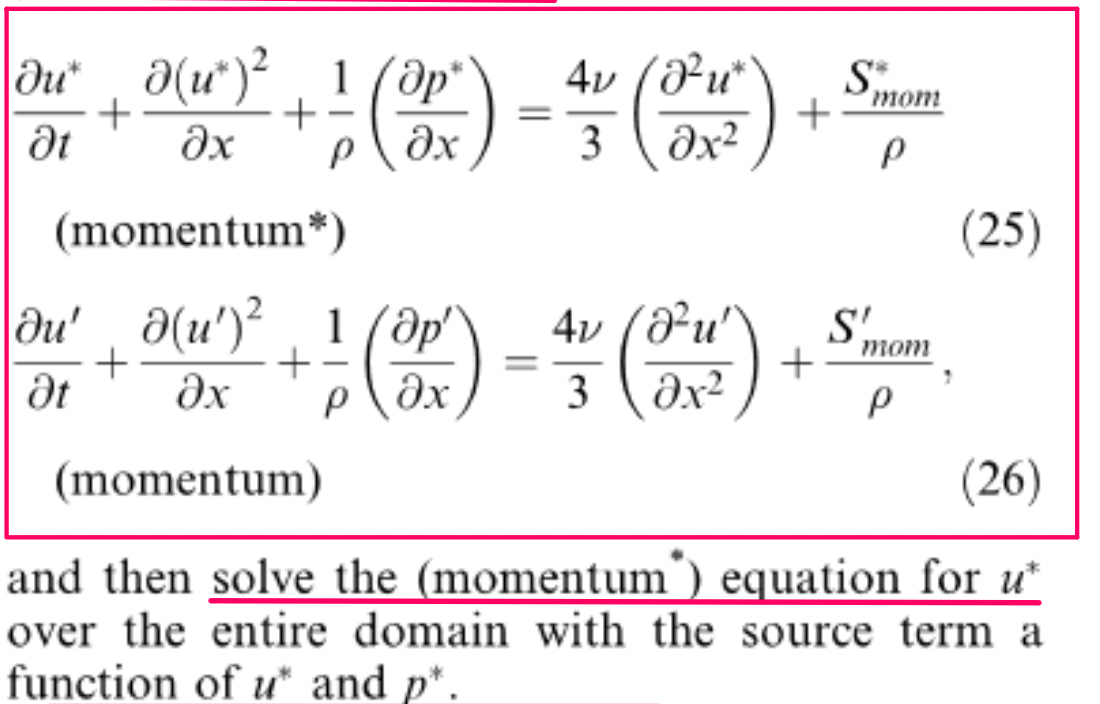

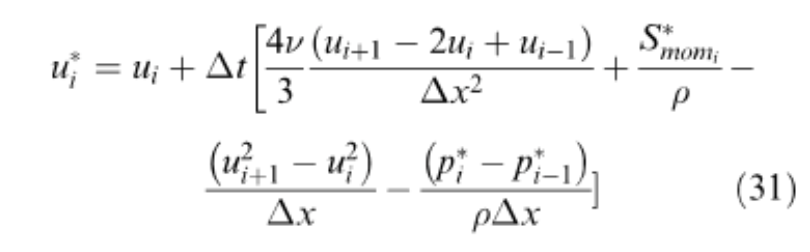

    % Specify the b.c.
u_star(1) = u_star(2);
u_star(N_cells) = u_in;

    % %%% 3. Solve the pressure-correction equation to find p' (Equation 30) %%%
    % for i=1:N_cells
    %     Smom(i) = fric(rho(i), u_prime(i), d_h, mu,L);
    % end
    % 
    % 
    % error = 1000;
    % dtit = 0;
    % while ((error > tolerance) && (dtit < 10000))
    %     error = 0;
    %     dtit = dtit + 1;
    %     for i=2:N_cells-1
    %         pold = p_prime(i);
    %         p_prime(i) = (1/2)*(p_prime(i+1) + p_prime(i-1) - dx*(rho(i)/dt*((u_star(i+1)-u_star(i)) - Smass(i)) + (Smom(i+1)-Smom(i-1))/2));
    %         error = max(error, abs(p_prime(i)-pold));
    %     end
    %     % Specify the b.c.
    %     p_prime(1) = 0; % Boundary condition for correction pressure (Equation 35)
    %     ugc = u_prime(N_cells);
    %     Sprs(N_cells) = Smom(N_cells) - 2*u_prime(N_cells)*Smass(N_cells) + 4*mu/3*(ugc - 2*u_prime(N_cells) + u_prime(N_cells-1))/dx/dx;
    %     p_prime(N_cells) = p_prime(N_cells-1) + Sprs(N_cells)*dx;
    % end

    % %%% 4. Correct the velocity using pressure correction (Equation 36) %%%
    % for i=2:N_cells-1
    %     error = 1000;
    %     dtit = 0;
    %     while ((error > tolerance) && (dtit < 10000))
    %         error = 0;
    %         dtit = dtit + 1;
    %         uold = u_prime(i);
    %         Smom(i) = fric(rho(i), u_prime(i), d_h, mu,L);
    %         u_prime(i) = dt/rho(i)/dx*(Smom(i)*dx - (p_prime(i)-p_prime(i-1)));
    %         error = max(error, abs(u_prime(i)-uold));
    %     end
    % end
    % u_prime(1) = u_prime(2);
    % u_prime(N_cells) = 0;

    % % 5. Correct the pressure and velocity (Equation 38)
    % tolerance = 0;
    % for i=1:N_cells
    %     tolerance = max(tolerance, abs(p(i) - (p_star(i)+alpha*p_prime(i))));
    %     tolerance = max(tolerance, abs(u(i) - (u_star(i)+u_prime(i))));
    %     p(i) = p_star(i) + alpha*p_prime(i);
    %     u(i) = u_star(i) + u_prime(i);
    %     u_star(i) = u(i);
    % end
    % 
    iteration = iteration + 1;
end

p_star =       101320      101320      101320      101320      101320


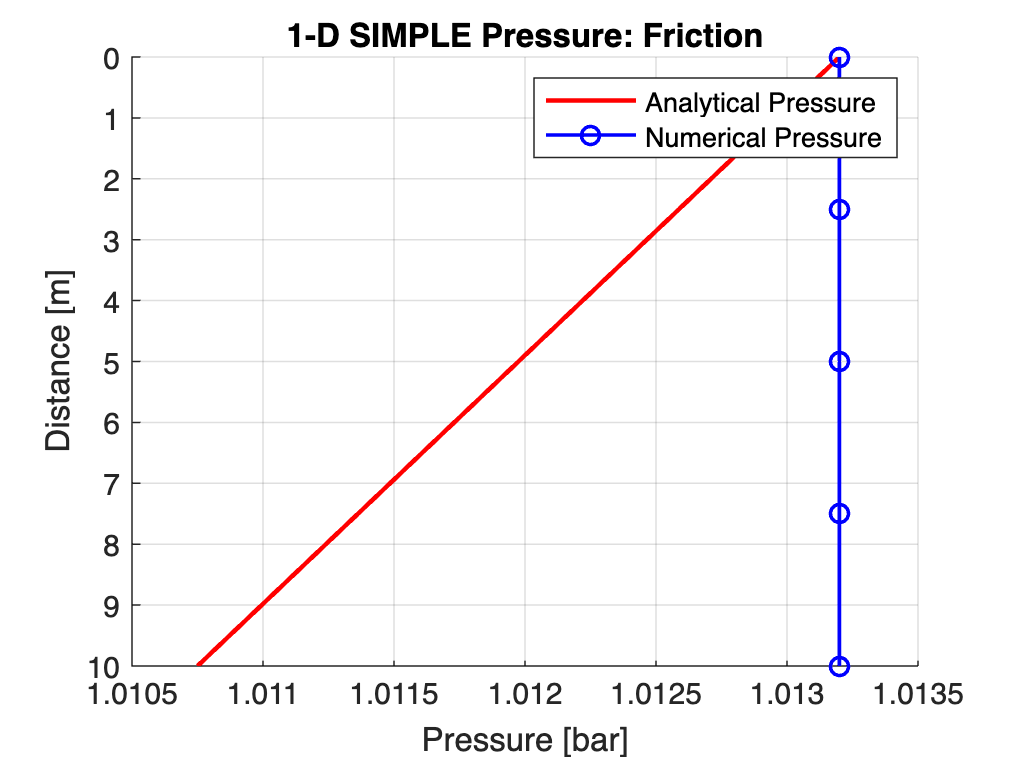

% Analytical Solution Parameters
Re = (rho_in * u_in * d_h) / mu;       % Reynolds number
f_D = 64 / Re;                     % Darcy friction factor (laminar flow)
dpdx = -f_D * (rho_in * u_in^2) / (2 * d_h);  % Pressure gradient
p_analytical = p_in + dpdx * x;     % Analytical pressure solution
r = linspace(0, d_h / 2, N_cells);       % Radial distance from pipe center to wall [m]
u_profile_analytical = u_in * (1 - (r / (d_h / 2)).^2); % Parabolic velocity profile
u_profile_numerical = u_in * u(1:end);  
% Plot Pressure (Numerical and Analytical)
figure;
hold on;
plot(p_analytical / 1e5, x, 'r-', 'LineWidth', 1.5); 
plot(p / 1e5, x, 'bo-', 'LineWidth', 1.2);          
xlabel('Pressure [bar]');
ylabel('Distance [m]');
title('1-D SIMPLE Pressure: Friction');
grid on;
legend('Analytical Pressure', 'Numerical Pressure');
set(gca, 'YDir', 'reverse'); 
hold off;

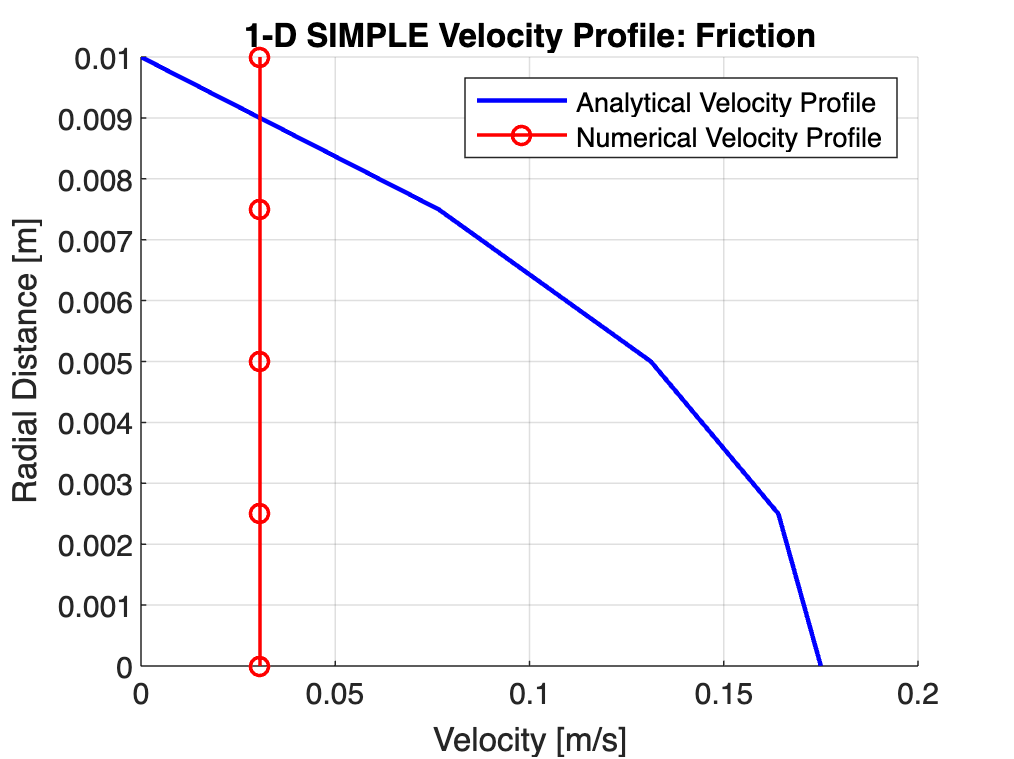

% Plot Velocity Profile
figure;
hold on;
plot(u_profile_analytical, r, 'b-', 'LineWidth', 1.5); 
plot(u_profile_numerical, r, 'ro-', 'LineWidth', 1.2); 
xlabel('Velocity [m/s]');
ylabel('Radial Distance [m]');
title('1-D SIMPLE Velocity Profile: Friction');
grid on;
legend('Analytical Velocity Profile', 'Numerical Velocity Profile');
hold off;

function Smom = fric(rho, u, d_h, mu, L)
    % Calculate Reynolds number
    Re = rho * abs(u) * d_h / mu; % Eqn 14

    % Compute Darcy friction factor (Moody's formula) for laminar flow (Re < 2300)
    if Re < 2300
        fM = 64 / Re;  % Eqn 13 % Moody friction factor for laminar flow
    else
        error('The provided equations are for laminar flow only (Re < 2300).');
    end

    % Convert Darcy friction factor to Fanning friction factor
    fF = fM / 4; % Eqn 15

    % Calculate cross-sectional area and volume terms (if needed, modify accordingly)
    A_s = pi * (d_h / 2)^2;  % Cross-sectional area of the pipe [m^2]
    V = A_s*L;               % Control volume is cross-sectional area times pipe length [m^3]

    % Compute the momentum source term for friction
    Smom = -rho * fF * u * abs(u) * A_s / (2 * V); % Eqn 12
end

function Smass = calculate_mass_source(~, ~, ~)
    % % Calculate mass source term for continuity equation
    % N_cells = length(u);
    % Smass = zeros(1, N_cells);
    % for i = 2:N_cells-1
    %     Smass(i) = rho * (u(i) - u(i-1)) / dx; % Discrete divergence of velocity
    % end
    % % Apply boundary conditions
    % Smass(1) = 0; % Inlet (no mass imbalance at boundary)
    % Smass(end) = 0; % Outlet (no mass imbalance at boundary)
    Smass = 0;
end
